# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 10;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.1; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 4.163415 seconds


Section took 4.040436 seconds


Section took 4.147859 seconds


Section took 4.161577 seconds


Section took 4.402627 seconds


Section took 4.338431 seconds


Section took 4.362402 seconds


Section took 4.473471 seconds


Section took 4.224482 seconds


Section took 4.332531 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.608517 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.94
Section took 0.601885 seconds


Section took 1.353708 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.478172 seconds


Section took 1.522437 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.528957 seconds


Section took 1.360136 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.91
Section took 0.478430 seconds


Section took 1.444152 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.93
Section took 0.481624 seconds


Section took 1.374046 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.458281 seconds


Section took 1.356510 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.455576 seconds


Section took 1.354721 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.482097 seconds


Section took 1.358218 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.460334 seconds


Section took 1.346451 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.454678 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.260047 seconds


Section took 2.323507 seconds


Section took 2.548858 seconds


Section took 2.391368 seconds


Section took 2.417937 seconds


Section took 2.353000 seconds


Section took 2.312573 seconds


Section took 2.380818 seconds


Section took 2.392489 seconds


Section took 2.353165 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.240954 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.487378 seconds


Section took 1.249046 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.472722 seconds


Section took 1.364682 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.531816 seconds


Section took 1.224474 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.470658 seconds


Section took 1.238654 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.477653 seconds


Section took 1.254228 seconds
Usable Spectral Fraction old = 0.96
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.457284 seconds


Section took 1.227979 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.463189 seconds


Section took 1.276381 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.488113 seconds


Section took 1.213857 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.469970 seconds


Section took 1.248776 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.462909 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 1.776866 seconds


Section took 1.788241 seconds


Section took 1.956784 seconds


Section took 1.852158 seconds


Section took 1.910120 seconds


Section took 1.795081 seconds


Section took 1.817930 seconds


Section took 1.853794 seconds


Section took 1.820750 seconds


Section took 1.796920 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.225168 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.463826 seconds


Section took 1.229037 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.495373 seconds


Section took 1.253165 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.501781 seconds


Section took 1.248202 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.78
Section took 0.469357 seconds


Section took 1.284054 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.479437 seconds


Section took 1.225817 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.476398 seconds


Section took 1.249728 seconds
Usable Spectral Fraction old = 0.88
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.451508 seconds


Section took 1.238009 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.461755 seconds


Section took 1.226934 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.464914 seconds


Section took 1.256427 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.462855 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

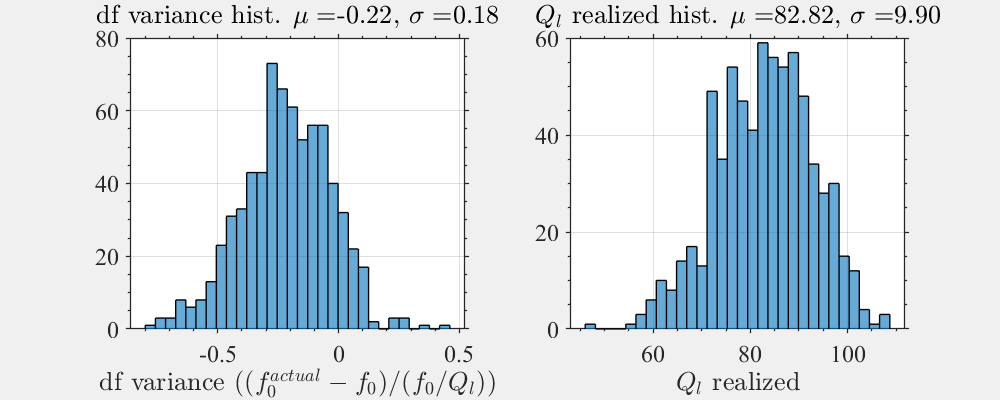

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

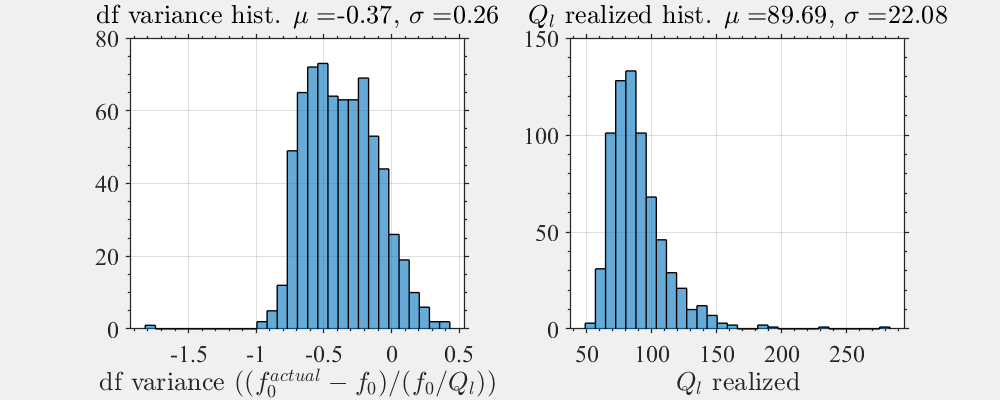


n_plot = 2;
showFilterBank(f,Data_refl);
showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

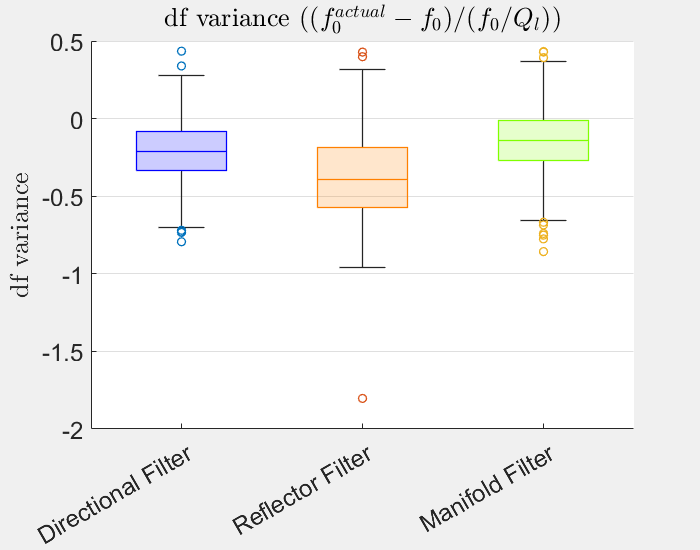

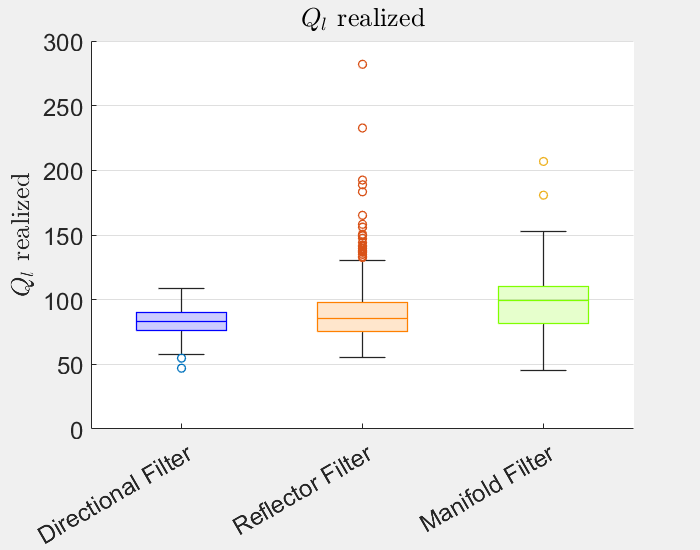

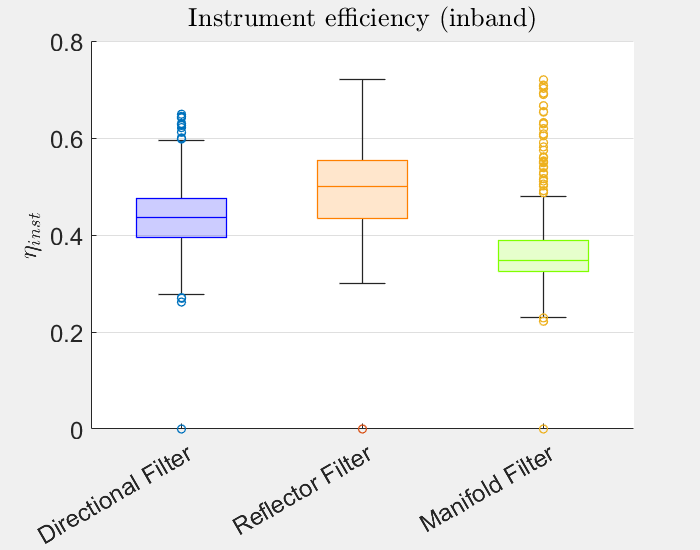

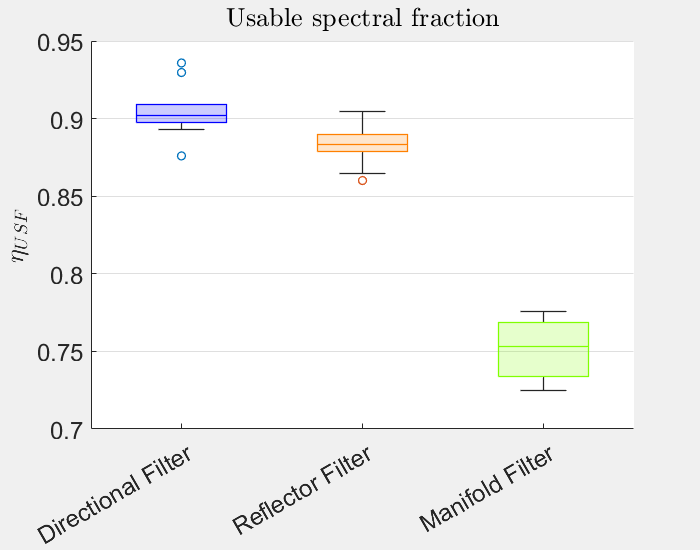

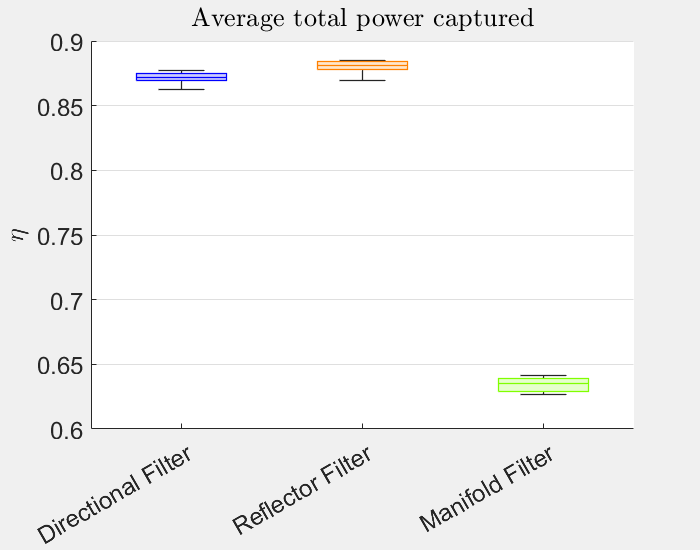

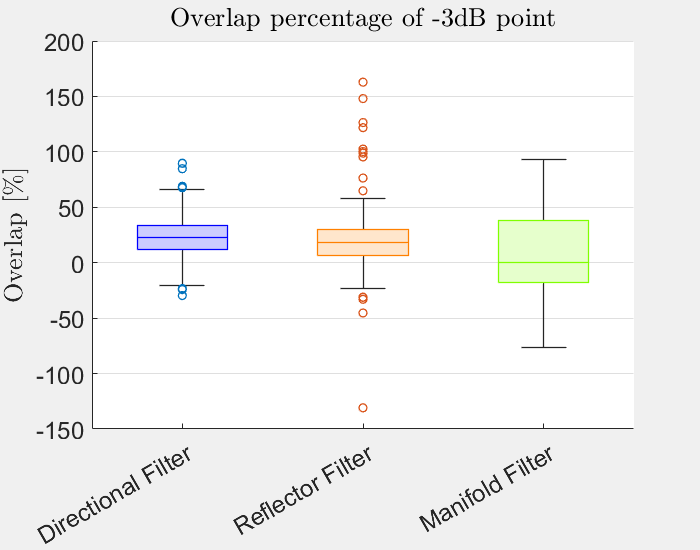

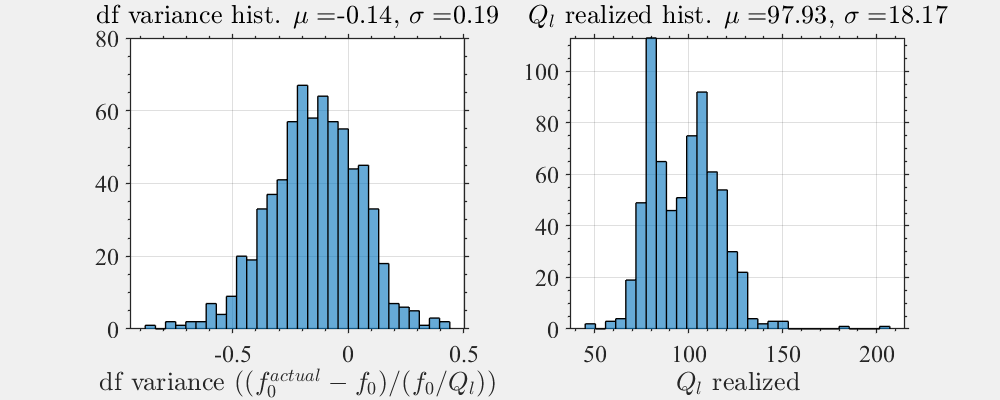



n_plot = 3;
showFilterBank(f,Data_man);
showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

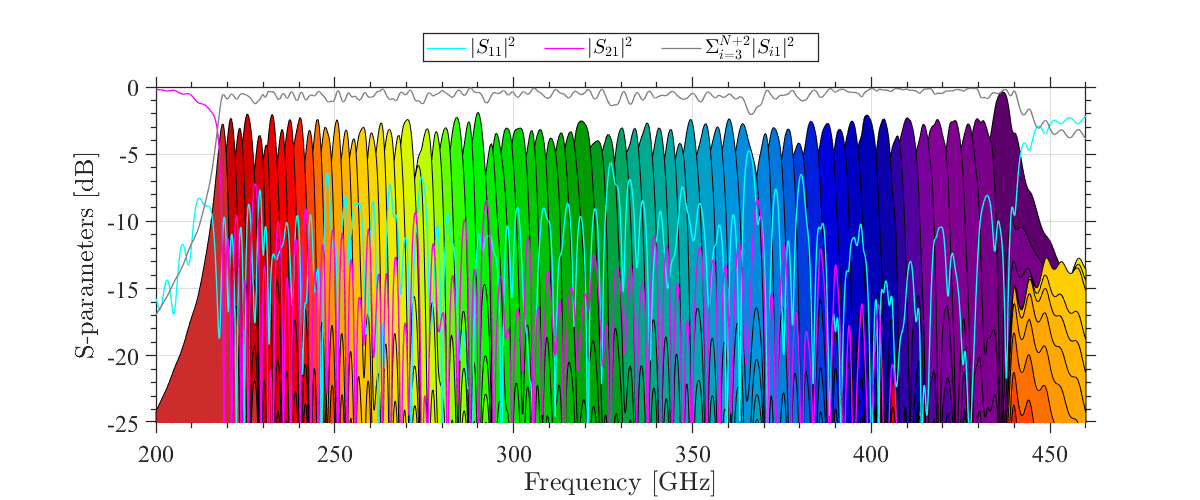

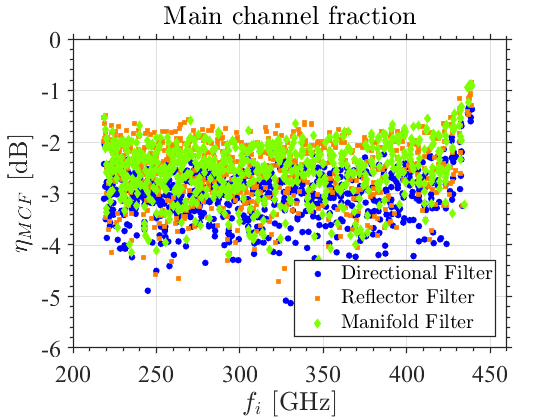

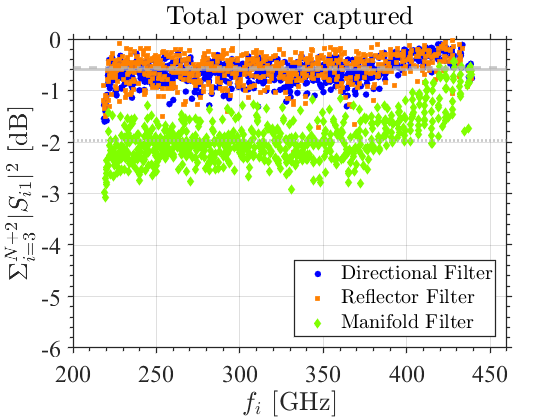

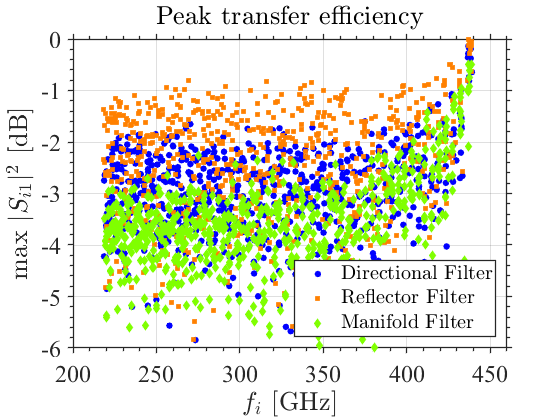

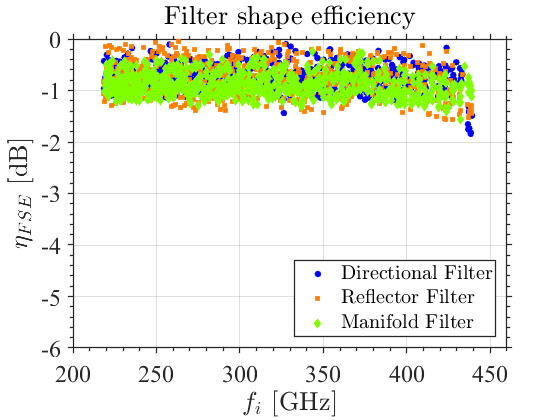

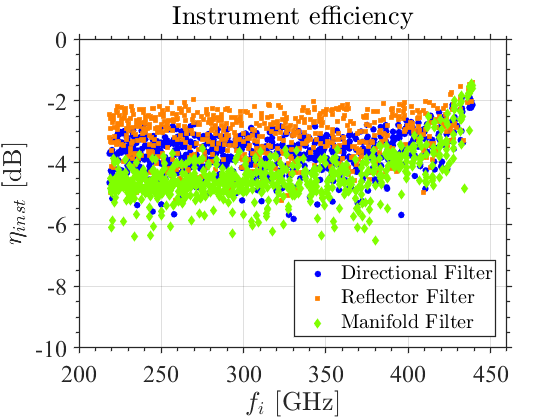

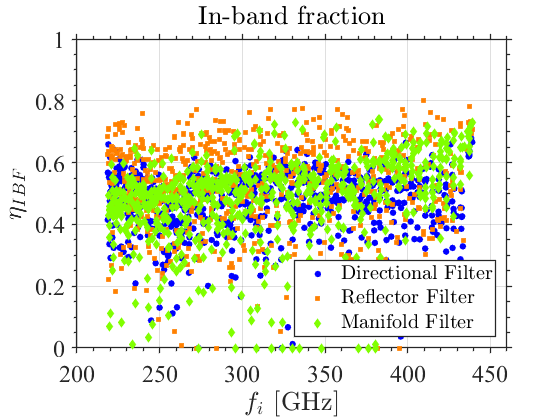

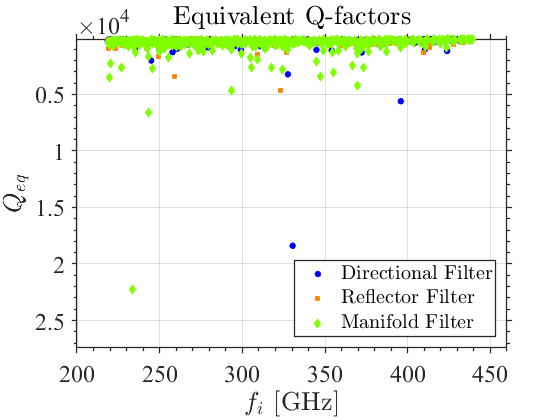



formatPlotting();